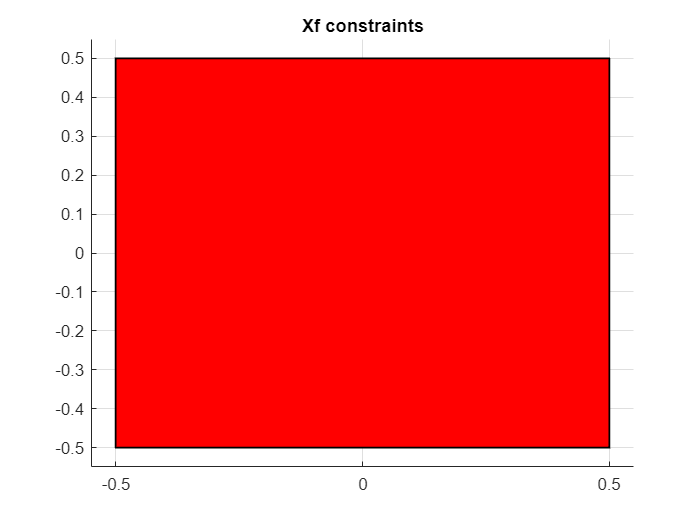

%%Stability for constrained systems
clc
clear

A = [2 0.1;0 1.5];
B = [0;1];
Q = [1 0;0 1];
R = 100;
N = 2;

model = LTISystem('A', A, 'B',B);
model.u.min = -1;
model.u.max =  1;

U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);

C = eye(2);
Xf_constraint =Polyhedron('A',[C;-C],'b',[0.5;0.5;0.5;0.5]); 
model.x.with('terminalSet');
model.x.terminalSet = Xf_constraint;
figure
plot(Xf_constraint)
title("Xf constraints")

%Find the largest control invariant set as the system's terminal set
Cinf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...
Iteration 33...
Iteration 34...
Iteration 35...
Iteration 36...
Iteration 37...
Iteration 38...
Iteration 39...
Iteration 40...
Iteration 41...
Iteration 42...
Iteration 43...
Iteration 44...
Iteration 45...
Iteration 46...
Iteration 47...
Iteration 48...
Iteration 49...
Iteration 50...
Iteration 51...
Iteration 52...
Iteration 53...
Iteration 54...
Iteration 55...
Iteration 56...
Iteration 57...


Xf = Cinf.intersect(Xf_constraint);      
model.x.with('terminalSet');

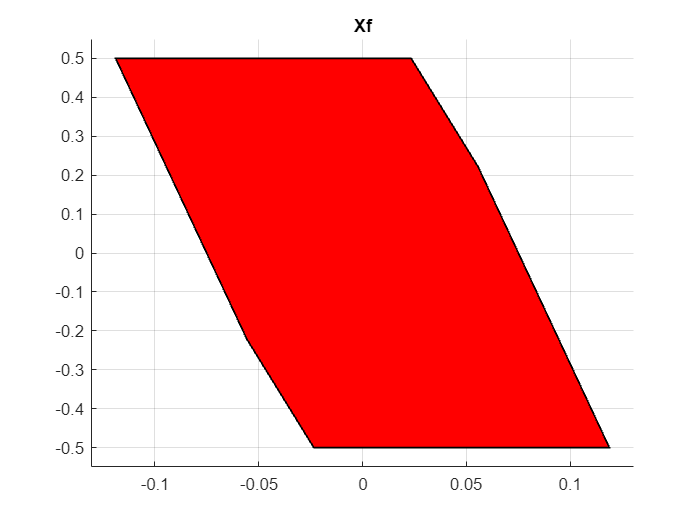

model.x.terminalSet = Xf;
figure
plot(Xf)
title("Xf")

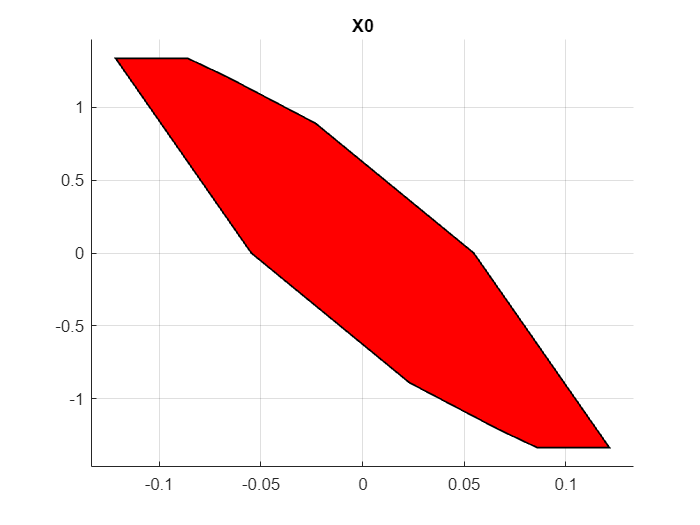

%Find its N-step backward reahable set 
XN = Xf;
for i=1:N
    back_XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = back_XN;
end
X0 = XN;
%Init condition
x0 = [-0.1;1.3];
figure
clf
plot(X0)
title("X0")

figure
plot(Xf)
title("Xf")

Nsim = 10;

%penalty is I2
Pf = eye(2);
model.x.with('terminalPenalty');
model.x.terminalPenalty = QuadFunction(Pf);

mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);
data  = loop.simulate(x0, Nsim);

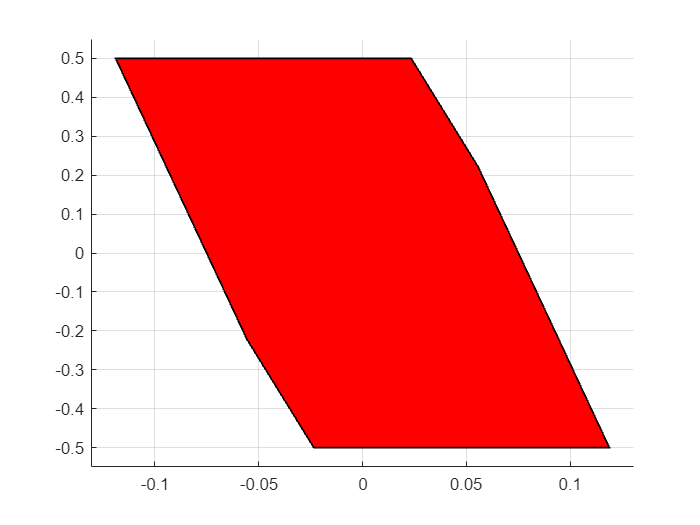


figure
clf; 
hold on;
% plot(X0)
plot(Xf)

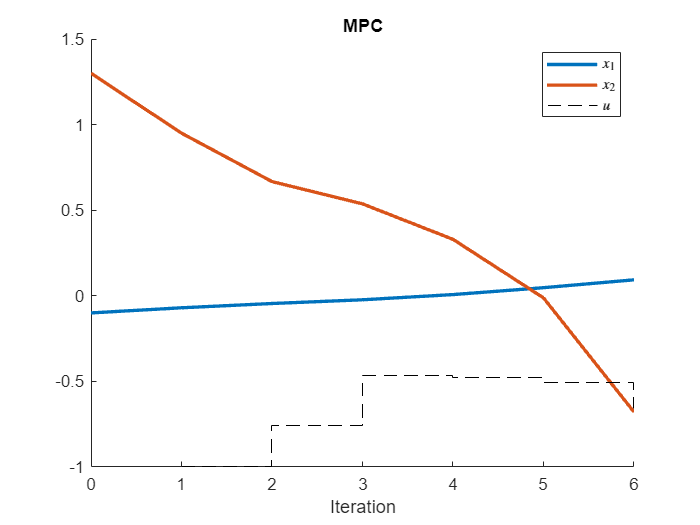

figure
hold on
Nsim = 6;
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')

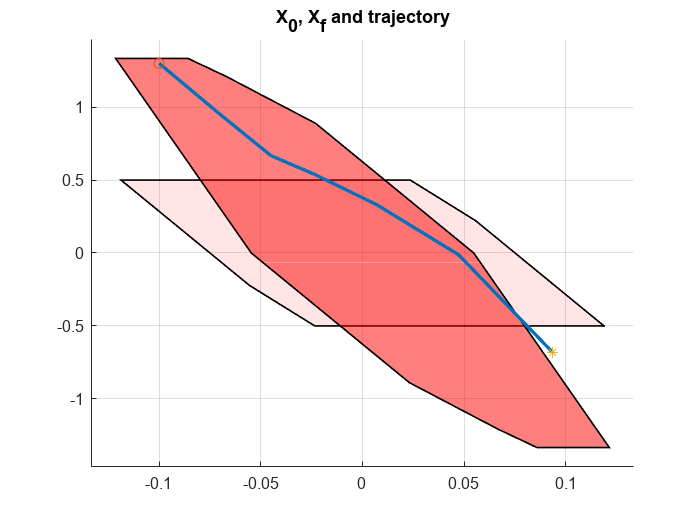


figure
hold on
plot(Xf, 'alpha', 0.1)
plot(X0, 'alpha', 0.5)
plot(data.X(1,:),data.X(2,:), 'Linewidth', 2)
scatter(x0(1), x0(2), 'o')
scatter(data.X(1,end), data.X(2,end), '*')
title('X_0, X_f and trajectory')

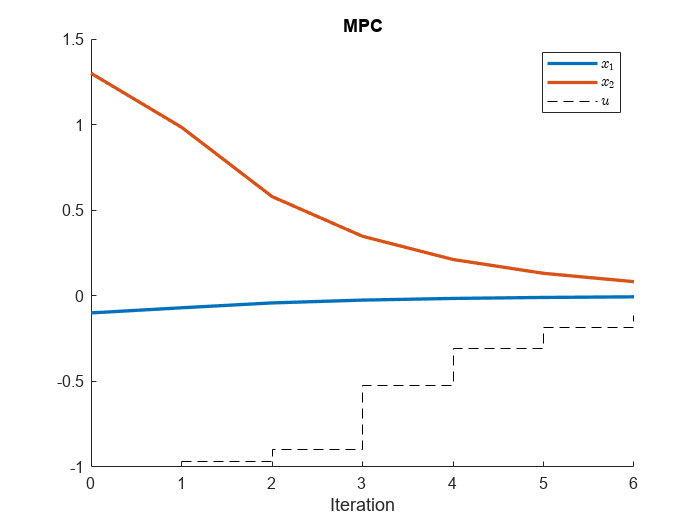


%penalty is Riccati solution
Pf = dare(A,B,Q,R);
model.x.terminalPenalty = QuadFunction(Pf);

mpc  = MPCController(model, N);
loop = ClosedLoop(mpc, model);
data  = loop.simulate(x0, Nsim);

figure
clf; 
hold on;
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')

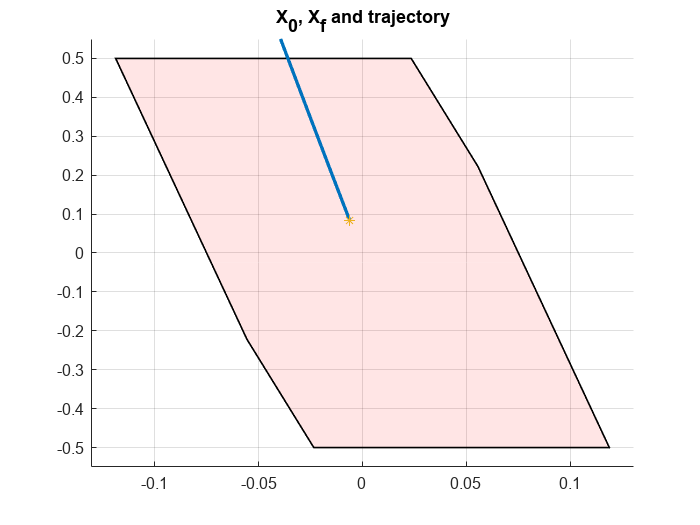


figure
hold on
plot(Xf, 'alpha', 0.1)
plot(data.X(1,:),data.X(2,:), 'Linewidth', 2)
scatter(x0(1), x0(2), 'o')
scatter(data.X(1,end), data.X(2,end), '*')
title('X_0, X_f and trajectory')